# Practice 2 (G)

# Risk factors 

This version: 02/08/2024

# Your name:

Edoardo Anfelli

Thaddeus Da Silva Correa

## **Questions (answers on the other pdf, with graph and tables well structured)**

 **(4 Points)**

- Explain the regression results of model_134. Are the regressors statistically significant?. Is the regression fit high or low?. Are the residuals independent and Normally distributed? (Hint: look for autocorrelation, heteroskedasticity and normality test in Matlab documentation)

# Write your answer here

1.

2. Is the CEI risk premium statistically significant?. Apply the proper test taking into account data characteristics. 

# Write your answer here

2.

3. Assume that CEI is the only relevant risk factor for AAA stock. The estimate of the CEI beta of stock AAA is 0.5. The one-year risk-free rate is 2%. What is the expected yearly excess return of stock AAA?. Explain the result. Assume that CEI is the only relevant risk factor for BBB stock. The estimate of the CEI beta of stock BBB is -1.4 The one-year risk-free rate is 2%. What is the expected yearly excess return of stock BBB?. Assume that CEI is the only relevant risk factor for CCC stock. The estimate of the CEI beta of stock CCC is 1.8 The one-year risk-free rate is 2%. What is the expected yearly excess return of stock CCC?. Explain the result. The variance of AAA, BBB and CCC excess returns is 0.23, 0.11 and 0.09 respectively and the correlations are: (AAA,BBB)  -0.34, (AAA,CCC) 0.15, (BBB,CCC) -0.19 . Suggest an investment strategy using AAA, BBB, and CCC stocks based on these results.

# Write your answer here

3.

4. You present your results in a seminar. A colleague indicates that the CEI premium may be linked to traditional risk factors. She suggests that the CEI risk premium you calculated will be a biased estimate compared to the proper premium. She points out that data on the most critical risk factor (the market) is available on MarketRP_2024.mat. Propose a method for finding an appropriate estimate of the CEI premium after adjusting for the market risk factor exposure. Present the numerical results and discuss them. Is your colleague right or wrong?

# Write your answer here

4.

Email to ypenya@eco.uc3m.es your response in a PDF file (Hint: Save a PDF version of your *.mlx file)

# Do not write in this section

q1 part 1

You are looking for factors effective at explaining realized return variation of 200 firms' stocks using yearly data from 1950 to 2022, using 73 data points for each stock. You compute stock returns r(i,t)  i=1,…,200  t=1,…,72. The factor you study, CEI(i,t), is firm *i* Carbon Emission Intensity (CEI) on year *t.* Carbon emission intensity (CEI) is calculated as tons of CO2 equivalent divided by the company revenues in million U.S. dollars.

You apply the Fama-MacBeth method to identify risk factors.

First, you run 200 time-series regressions  r(i,t) = a(i)+b(i)CEI(i,t) + e(i,t) .

The data for regression number 134 is in CEI_134.mat and ExcessreturnAsset_134.mat 

% Run a linear regression
tblrent1 = table(ExcessreturnAsset_134,CEI_134,...
    'VariableNames',{'ExcessreturnAsset_134', 'CEI_134'});
model_134=fitlm (tblrent1, 'ExcessreturnAsset_134~CEI_134')

model_134 = Linear regression model:
    ExcessreturnAsset_134 ~ 1 + CEI_134

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)    -0.46056    0.51335    -0.89717       0.37266
    CEI_134           1.612    0.44177      3.6489    0.00049926


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 0.994
R-squared: 0.158,  Adjusted R-Squared: 0.146
F-statistic vs. constant model: 13.3, p-value = 0.000499

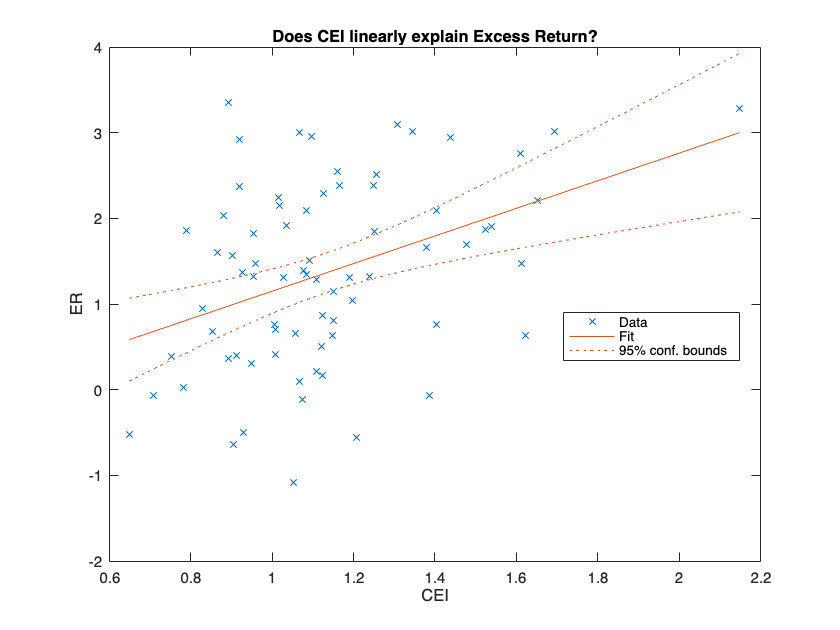

plot(model_134)
title('Does CEI linearly explain Excess Return?')
xlabel('CEI')
ylabel('ER')

q1 part 2

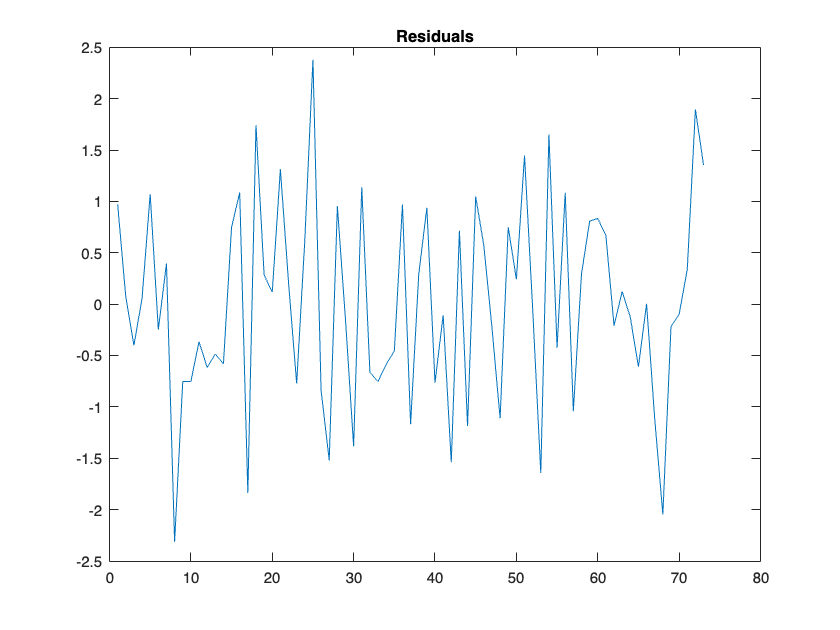

% Get model residuals (=OBSERVEDY-PREDICTEDY)
resid_134=model_134.Residuals.Raw;
plot(resid_134)
title('Residuals')

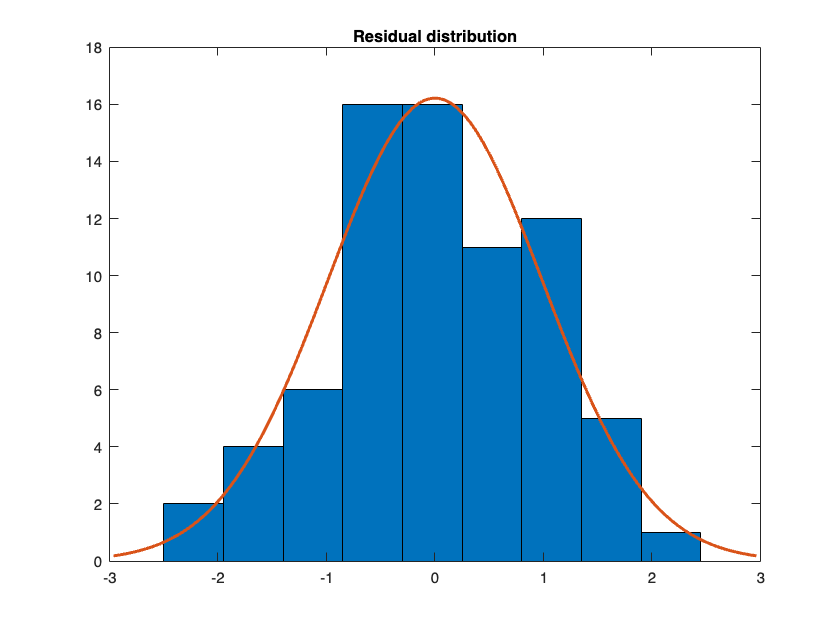

% Normality of residuals
histfit(resid_134)
title('Residual distribution')

% Jarque-Bera Test on residuals
[h, p, jbstat] = jbtest(resid_134);

% Results
disp(['Test statistic (JB): ', num2str(jbstat)]);

Test statistic (JB): 0.49848


disp(['p-value: ', num2str(p)]);

p-value: 0.5


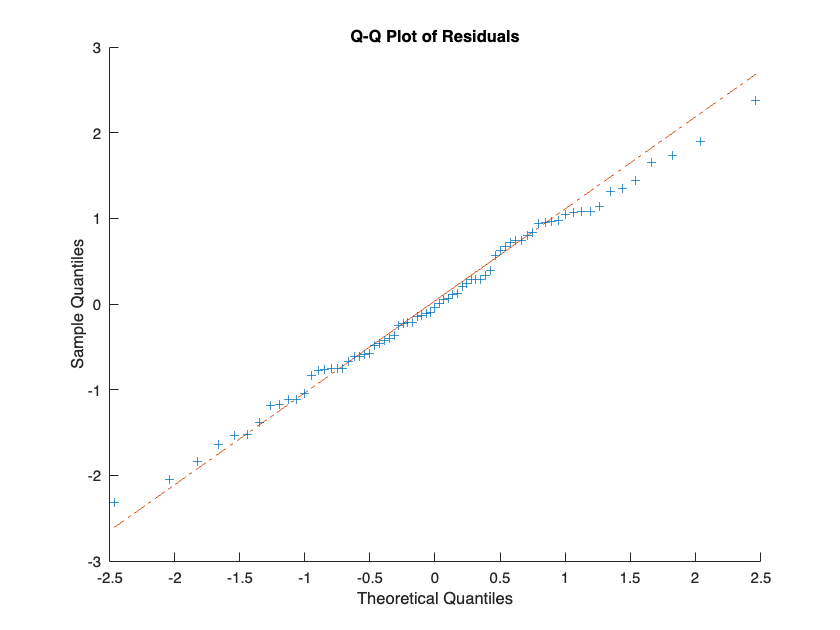

%JB gave us a strange result, probably because of the dimension of the
%sample, let's try another test (Kolmogorov-Smirnov) e try to view normality with the QQplot
% QQplot
qqplot(resid_134);
title('Q-Q Plot of Residuals');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');

%The more the points are close to the line, the more are distributed N
% Kolmogorov-Smirnov Test
[h, pValue] = kstest(resid_134);

% Results Ktest
disp(['p-value: ', num2str(pValue)]);

p-value: 0.98884


% Heteroskedasticity of residuals
% Breusch-Pagan calculated by hand cause function didn't work
% Define independent var and residuals
X = [ones(size(ExcessreturnAsset_134)), ExcessreturnAsset_134]; % Add column of 1 
residuals = resid_134;

% Find R2 by hand because function didn't work 
n = length(residuals); 
residuals_sq = residuals.^2; 
b = regress(residuals_sq, X); 
SSR = sum(residuals_sq); %(SSR)
TSS = sum((residuals_sq - mean(residuals_sq)).^2); %(TSS)
R2 = SSR / TSS; % Calcola il R^2

% Breusch-Pagan test 
BP_stat = n * R2; 

%  p-value based on the chi-squared distribution with df = k-1
df = size(X, 2) - 1; % Gradi di libertà (numero di regressori - 1)
pval = 1 - chi2cdf(BP_stat, df);

% Results
disp(['Breusch-Pagan Test Statistic: ', num2str(BP_stat)]);

Breusch-Pagan Test Statistic: 47.4547


disp(['p-value del test di Breusch-Pagan: ', num2str(pval)]);

p-value del test di Breusch-Pagan: 5.6291e-12


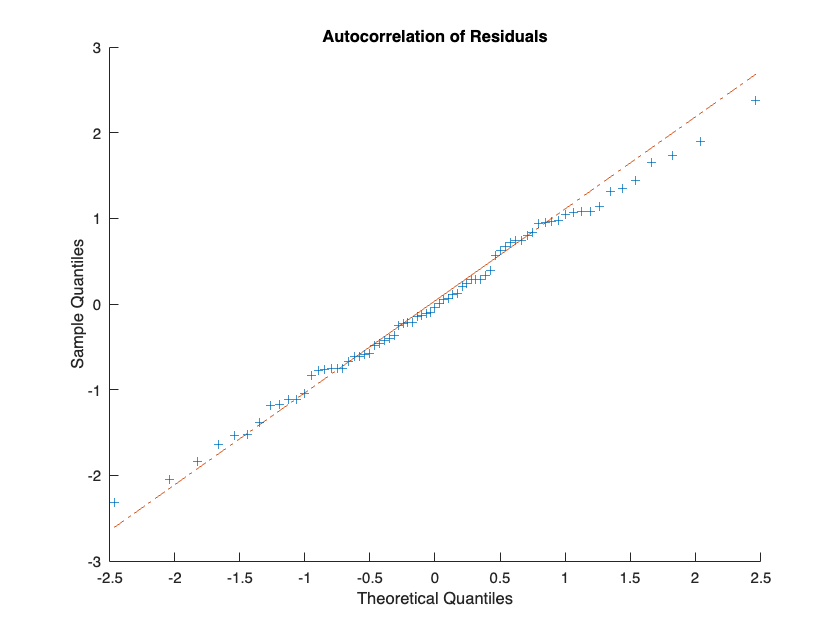

% Autocorrelation of residuals
autoc_res = autocorr(resid_134); 
title('Autocorrelation of Residuals');

mean(autoc_res)

ans = 0.0196

q2

In 187 regressions out of 200 you reject the null hypothesis that b(i) =  0. 

Following the second step of the Fama-MacBeth method, you form 20 portfolios of 10 stocks, ordered by the size of b(i), and average their returns and betas yearly. Therefore, every year t, you have twenty average returns r*(j) j=1,…,20, and twenty average betas b(j).  You run 72 cross-section regressions r*(j,t) = a(0,t) + a(1,t)b(j,t) + n(j,t)  and get 72 estimates of the CEI risk premium parameter a(1,t) t=1,..,72. 

The data of the CEI risk premium time series is in variable CEI_RP

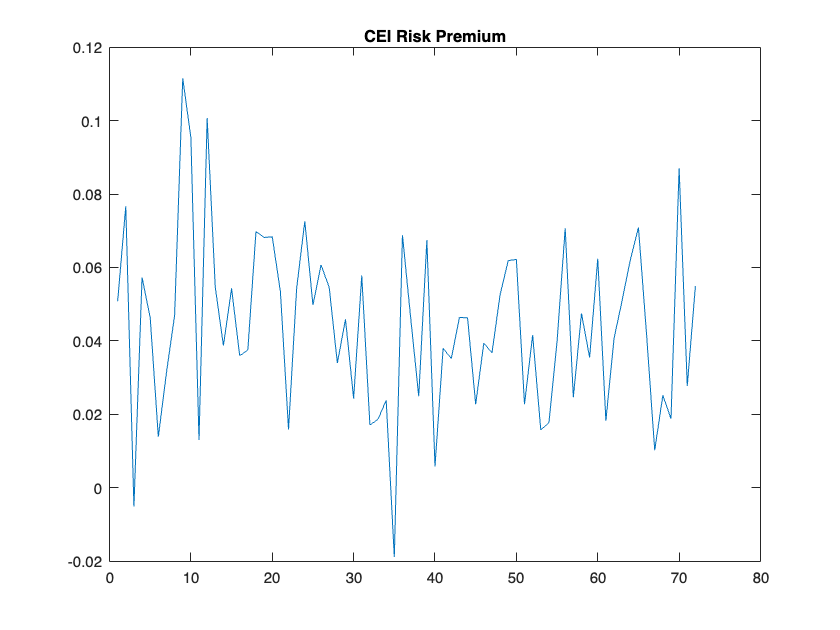

plot(CEI_RP)
title('CEI Risk Premium')

% Descriptive statistics CEI_RP
T1=table(mean(CEI_RP), max(CEI_RP),min(CEI_RP), std(CEI_RP),skewness(CEI_RP), kurtosis(CEI_RP), quantile(CEI_RP,0.01), quantile(CEI_RP,0.99),quantile(CEI_RP,0.0001), quantile(CEI_RP,0.9999));
T1.Properties.VariableNames = {'Mean','Max','Min', 'STD', 'Skew', 'Kurt', 'Q0.01','Q0.99','Q0.0001','Q0.9999'};
vr={'CEI_RP'};
T1.Properties.RowNames = vr

T1 = 1×10 table
                Mean        Max         Min         STD        Skew       Kurt      Q0.01       Q0.99      Q0.0001     Q0.9999
              ________    _______    _________    ________    _______    ______    ________    _______    _________    _______

    CEI_RP    0.044034    0.11157    -0.018886    0.024032    0.19992    3.3538    -0.01587    0.10918    -0.018886    0.11157


% Significance test CEI_RP
% Calculate Mean and Standard Deviation
mean_premium = 0.0440;
std_dev_premium = 0.0240;
n = length(CEI_RP);


% Conduct the t-test
mu_0 = 0;  % Hypothesized mean
t_statistic = (mean_premium - mu_0) / (std_dev_premium / sqrt(n));
df = n - 1;  % Degrees of freedom


% Calculate p-value
p_value = 2 * (1 - tcdf(abs(t_statistic), df));  % Two-tailed p-value


% Output Results
fprintf('T-statistic: %.4f\n', t_statistic);

T-statistic: 15.5563


fprintf('P-value: %.4f\n', p_value);

P-value: 0.0000


%checking if data are stationary
[h_rp, pValue_rp] = adftest(CEI_RP);
disp(['CEI Risk Premium ADF p-value: ', num2str(pValue_rp)]);

CEI Risk Premium ADF p-value: 0.0035529



%Test for stationaryness
[h, pValue, stat, cValue, reg] = adftest(CEI_RP);

% Display the results
disp(['ADF Test Result: ', num2str(h)]);

ADF Test Result: 1


disp(['P-value: ', num2str(pValue)]);

P-value: 0.0035529


disp(['Test Statistic: ', num2str(stat)]);

Test Statistic: -3.038


disp('Critical Values:');

Critical Values:


disp(cValue);

   -1.9449



q3 part 1

% Portfolios
betaA = 0.5

betaA = 0.5000

betaB =-1.4

betaB = -1.4000

betaC=1.8

betaC = 1.8000

rf=0.02

rf = 0.0200

% We don't have any tipe of shocks (asset or factor)

% Excess return AAA BBB CCC, = beta * RP - rf
erA=betaA .* CEI_RP - rf

erA =     0.0054
    0.0183
   -0.0226
    0.0086
    0.0032
   -0.0131
   -0.0043
    0.0034
    0.0358
    0.0277


erB=betaB .* CEI_RP - rf

erB =    -0.0911
   -0.1273
   -0.0128
   -0.1001
   -0.0849
   -0.0394
   -0.0639
   -0.0856
   -0.1762
   -0.1535


erC=betaC .* CEI_RP - rf

erC =     0.0714
    0.1180
   -0.0293
    0.0830
    0.0635
    0.0049
    0.0364
    0.0643
    0.1808
    0.1517


TA=table(mean(erA), max(erA),min(erA), std(erA),skewness(erA), kurtosis(erA));
TA.Properties.VariableNames = {'Mean','Max','Min', 'STD', 'Skew', 'Kurt'};
rowname = {'ExcessReturnAAA'}

rowname = 1×1 cell array
    {'ExcessReturnAAA'}


TA.Properties.RowNames = rowname

TA = 1×6 table
                         Mean         Max          Min         STD        Skew       Kurt 
                       _________    ________    _________    ________    _______    ______

    ExcessReturnAAA    0.0020169    0.035784    -0.029443    0.012016    0.19992    3.3538



TB=table(mean(erB), max(erB),min(erB), std(erB),skewness(erB), kurtosis(erB));
TB.Properties.VariableNames = {'Mean','Max','Min', 'STD', 'Skew', 'Kurt'};
rowname = {'ExcessReturnBBB'}

rowname = 1×1 cell array
    {'ExcessReturnBBB'}


TB.Properties.RowNames = rowname

TB = 1×6 table
                         Mean         Max        Min        STD         Skew       Kurt 
                       _________    _______    _______    ________    ________    ______

    ExcessReturnBBB    -0.081647    0.00644    -0.1762    0.033645    -0.19992    3.3538



TC=table(mean(erC), max(erC),min(erC), std(erC),skewness(erC), kurtosis(erC));
TC.Properties.VariableNames = {'Mean','Max','Min', 'STD', 'Skew', 'Kurt'};
rowname = {'ExcessReturnCCC'}

rowname = 1×1 cell array
    {'ExcessReturnCCC'}


TC.Properties.RowNames = rowname

TC = 1×6 table
                         Mean        Max         Min         STD        Skew       Kurt 
                       ________    _______    _________    ________    _______    ______

    ExcessReturnCCC    0.059261    0.18082    -0.053994    0.043258    0.19992    3.3538


varA=0.23 

varA = 0.2300

varB=0.11

varB = 0.1100

varC=0.09

varC = 0.0900

corrAB= -0.34

corrAB = -0.3400

corrAC=0.15 

corrAC = 0.1500

corrBC=-0.19

corrBC = -0.1900

% Strategies
% Define expected returns and covariance matrix
mu = [0.0020; -0.0816; 0.0593]; % Expected returns for AAA, BBB, and CCC
Sigma = [0.012^2, -0.00013622, 0.00007794;
         -0.00013622, 0.0336^2, -0.00027608;
         0.00007794, -0.00027608, 0.0433^2]; % Covariance matrix

% Number of portfolios to generate (n)
numPortfolios = 100; 
positiveTargetReturns = linspace(0.0020, max(mu), numPortfolios); % Target returns (positive only)

% Pre-allocate arrays for storing risk, return, and weights
risk_short = zeros(numPortfolios, 1);
return_short = zeros(numPortfolios, 1);
weights_short = zeros(numPortfolios, 3); % For storing weights of each portfolio

% Define the constraint for sum of weights = 1
Aeq = [ones(1, 3)];  % Ensures weights sum to 1
beq = 1;             % The sum must be 1

% Loop through positive target returns and compute n efficient portfolios with short-selling allowed
for i = 1:numPortfolios
    % Set positive target return
    targetReturn = positiveTargetReturns(i);

    % The objective is to minimize portfolio variance
    f = [];  % No linear term in quadratic programming
    H = Sigma;  % Quadratic term: portfolio variance
    
    % Add return constraint: Ensure portfolio return is equal to targetReturn
    A = [-mu']; % To match the target return
    b = -targetReturn;

    % Solve for short-selling allowed (no bounds on weights)
    lb = []; % No lower bound (short-selling allowed)
    ub = []; % No upper bound

    % Solve the quadratic programming problem to minimize risk for a target return
    [w_short, ~] = quadprog(H, f, A, b, Aeq, beq, lb, ub);

    % Store portfolio return, risk, and weights for short-selling
    return_short(i) = mu' * w_short; % Expected return
    risk_short(i) = sqrt(w_short' * Sigma * w_short); % Portfolio risk (standard deviation)
    weights_short(i, :) = w_short'; % Store the weights of the portfolio
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


% Plot the efficient frontier for short-selling allowed
figure('Visible','on')
plot(risk_short, return_short, 'r', 'LineWidth', 2); % Short-selling allowed
xlabel('Risk (Standard Deviation)');
ylabel('Return');
title('Efficient Frontier with Short-Selling Allowed (Positive Returns)');
grid on;

% Display the n portfolios with positive returns
disp('100 Portfolios on the Efficient Frontier with Positive Returns:');

100 Portfolios on the Efficient Frontier with Positive Returns:


for i = 1:numPortfolios
    disp(['Portfolio ', num2str(i), ':']);
    disp([' - Target Return: ', num2str(return_short(i))]);
    disp([' - Risk (Standard Deviation): ', num2str(risk_short(i))]);
    disp([' - Weights: [AAA: ', num2str(weights_short(i, 1)), ', BBB: ', num2str(weights_short(i, 2)), ', CCC: ', num2str(weights_short(i, 3)), ']']);
end

Portfolio 1:


 - Target Return: 0.002


 - Risk (Standard Deviation): 0.010827


 - Weights: [AAA: 0.82513, BBB: 0.071114, CCC: 0.10375]


Portfolio 2:


 - Target Return: 0.0025788


 - Risk (Standard Deviation): 0.010942


 - Weights: [AAA: 0.82743, BBB: 0.06607, CCC: 0.1065]


Portfolio 3:


 - Target Return: 0.0031613


 - Risk (Standard Deviation): 0.011063


 - Weights: [AAA: 0.82975, BBB: 0.060994, CCC: 0.10926]


Portfolio 4:


 - Target Return: 0.0037391


 - Risk (Standard Deviation): 0.011186


 - Weights: [AAA: 0.83205, BBB: 0.055959, CCC: 0.11199]


Portfolio 5:


 - Target Return: 0.0043172


 - Risk (Standard Deviation): 0.011312


 - Weights: [AAA: 0.83435, BBB: 0.050921, CCC: 0.11473]


Portfolio 6:


 - Target Return: 0.0048955


 - Risk (Standard Deviation): 0.011443


 - Weights: [AAA: 0.83665, BBB: 0.045882, CCC: 0.11747]


Portfolio 7:


 - Target Return: 0.0054739


 - Risk (Standard Deviation): 0.011576


 - Weights: [AAA: 0.83894, BBB: 0.040842, CCC: 0.12021]


Portfolio 8:


 - Target Return: 0.0060524


 - Risk (Standard Deviation): 0.011713


 - Weights: [AAA: 0.84125, BBB: 0.0358, CCC: 0.12295]


Portfolio 9:


 - Target Return: 0.0066309


 - Risk (Standard Deviation): 0.011852


 - Weights: [AAA: 0.84355, BBB: 0.030759, CCC: 0.1257]


Portfolio 10:


 - Target Return: 0.0072096


 - Risk (Standard Deviation): 0.011995


 - Weights: [AAA: 0.84585, BBB: 0.025716, CCC: 0.12844]


Portfolio 11:


 - Target Return: 0.0077882


 - Risk (Standard Deviation): 0.012141


 - Weights: [AAA: 0.84815, BBB: 0.020674, CCC: 0.13118]


Portfolio 12:


 - Target Return: 0.0083669


 - Risk (Standard Deviation): 0.012289


 - Weights: [AAA: 0.85045, BBB: 0.015631, CCC: 0.13392]


Portfolio 13:


 - Target Return: 0.0089457


 - Risk (Standard Deviation): 0.01244


 - Weights: [AAA: 0.85275, BBB: 0.010588, CCC: 0.13666]


Portfolio 14:


 - Target Return: 0.0095244


 - Risk (Standard Deviation): 0.012594


 - Weights: [AAA: 0.85505, BBB: 0.0055443, CCC: 0.1394]


Portfolio 15:


 - Target Return: 0.010103


 - Risk (Standard Deviation): 0.01275


 - Weights: [AAA: 0.85735, BBB: 0.00050091, CCC: 0.14215]


Portfolio 16:


 - Target Return: 0.010682


 - Risk (Standard Deviation): 0.012909


 - Weights: [AAA: 0.85965, BBB: -0.0045426, CCC: 0.14489]


Portfolio 17:


 - Target Return: 0.011261


 - Risk (Standard Deviation): 0.01307


 - Weights: [AAA: 0.86195, BBB: -0.0095861, CCC: 0.14763]


Portfolio 18:


 - Target Return: 0.011839


 - Risk (Standard Deviation): 0.013233


 - Weights: [AAA: 0.86426, BBB: -0.01463, CCC: 0.15037]


Portfolio 19:


 - Target Return: 0.012418


 - Risk (Standard Deviation): 0.013398


 - Weights: [AAA: 0.86656, BBB: -0.019673, CCC: 0.15312]


Portfolio 20:


 - Target Return: 0.012997


 - Risk (Standard Deviation): 0.013566


 - Weights: [AAA: 0.86886, BBB: -0.024717, CCC: 0.15586]


Portfolio 21:


 - Target Return: 0.013576


 - Risk (Standard Deviation): 0.013735


 - Weights: [AAA: 0.87116, BBB: -0.029761, CCC: 0.1586]


Portfolio 22:


 - Target Return: 0.014155


 - Risk (Standard Deviation): 0.013906


 - Weights: [AAA: 0.87346, BBB: -0.034804, CCC: 0.16134]


Portfolio 23:


 - Target Return: 0.014733


 - Risk (Standard Deviation): 0.014079


 - Weights: [AAA: 0.87576, BBB: -0.039848, CCC: 0.16408]


Portfolio 24:


 - Target Return: 0.015312


 - Risk (Standard Deviation): 0.014254


 - Weights: [AAA: 0.87806, BBB: -0.044892, CCC: 0.16683]


Portfolio 25:


 - Target Return: 0.015891


 - Risk (Standard Deviation): 0.014431


 - Weights: [AAA: 0.88037, BBB: -0.049935, CCC: 0.16957]


Portfolio 26:


 - Target Return: 0.01647


 - Risk (Standard Deviation): 0.014609


 - Weights: [AAA: 0.88267, BBB: -0.054979, CCC: 0.17231]


Portfolio 27:


 - Target Return: 0.017048


 - Risk (Standard Deviation): 0.014789


 - Weights: [AAA: 0.88497, BBB: -0.060023, CCC: 0.17505]


Portfolio 28:


 - Target Return: 0.017627


 - Risk (Standard Deviation): 0.014971


 - Weights: [AAA: 0.88727, BBB: -0.065066, CCC: 0.1778]


Portfolio 29:


 - Target Return: 0.018206


 - Risk (Standard Deviation): 0.015153


 - Weights: [AAA: 0.88957, BBB: -0.07011, CCC: 0.18054]


Portfolio 30:


 - Target Return: 0.018785


 - Risk (Standard Deviation): 0.015338


 - Weights: [AAA: 0.89187, BBB: -0.075154, CCC: 0.18328]


Portfolio 31:


 - Target Return: 0.019364


 - Risk (Standard Deviation): 0.015523


 - Weights: [AAA: 0.89417, BBB: -0.080197, CCC: 0.18602]


Portfolio 32:


 - Target Return: 0.019942


 - Risk (Standard Deviation): 0.015711


 - Weights: [AAA: 0.89648, BBB: -0.085241, CCC: 0.18877]


Portfolio 33:


 - Target Return: 0.020521


 - Risk (Standard Deviation): 0.015899


 - Weights: [AAA: 0.89878, BBB: -0.090285, CCC: 0.19151]


Portfolio 34:


 - Target Return: 0.0211


 - Risk (Standard Deviation): 0.016088


 - Weights: [AAA: 0.90108, BBB: -0.095329, CCC: 0.19425]


Portfolio 35:


 - Target Return: 0.021679


 - Risk (Standard Deviation): 0.016279


 - Weights: [AAA: 0.90338, BBB: -0.10037, CCC: 0.19699]


Portfolio 36:


 - Target Return: 0.022258


 - Risk (Standard Deviation): 0.016471


 - Weights: [AAA: 0.90568, BBB: -0.10542, CCC: 0.19973]


Portfolio 37:


 - Target Return: 0.022836


 - Risk (Standard Deviation): 0.016664


 - Weights: [AAA: 0.90798, BBB: -0.11046, CCC: 0.20248]


Portfolio 38:


 - Target Return: 0.023417


 - Risk (Standard Deviation): 0.016859


 - Weights: [AAA: 0.91029, BBB: -0.11552, CCC: 0.20523]


Portfolio 39:


 - Target Return: 0.023995


 - Risk (Standard Deviation): 0.017054


 - Weights: [AAA: 0.91259, BBB: -0.12056, CCC: 0.20797]


Portfolio 40:


 - Target Return: 0.024574


 - Risk (Standard Deviation): 0.01725


 - Weights: [AAA: 0.91489, BBB: -0.1256, CCC: 0.21071]


Portfolio 41:


 - Target Return: 0.025153


 - Risk (Standard Deviation): 0.017447


 - Weights: [AAA: 0.91719, BBB: -0.13064, CCC: 0.21345]


Portfolio 42:


 - Target Return: 0.025731


 - Risk (Standard Deviation): 0.017645


 - Weights: [AAA: 0.91949, BBB: -0.13569, CCC: 0.21619]


Portfolio 43:


 - Target Return: 0.02631


 - Risk (Standard Deviation): 0.017844


 - Weights: [AAA: 0.92179, BBB: -0.14073, CCC: 0.21893]


Portfolio 44:


 - Target Return: 0.026889


 - Risk (Standard Deviation): 0.018043


 - Weights: [AAA: 0.9241, BBB: -0.14577, CCC: 0.22168]


Portfolio 45:


 - Target Return: 0.027467


 - Risk (Standard Deviation): 0.018244


 - Weights: [AAA: 0.9264, BBB: -0.15081, CCC: 0.22442]


Portfolio 46:


 - Target Return: 0.028046


 - Risk (Standard Deviation): 0.018446


 - Weights: [AAA: 0.9287, BBB: -0.15586, CCC: 0.22716]


Portfolio 47:


 - Target Return: 0.028625


 - Risk (Standard Deviation): 0.018648


 - Weights: [AAA: 0.931, BBB: -0.1609, CCC: 0.2299]


Portfolio 48:


 - Target Return: 0.029203


 - Risk (Standard Deviation): 0.018851


 - Weights: [AAA: 0.9333, BBB: -0.16594, CCC: 0.23264]


Portfolio 49:


 - Target Return: 0.029782


 - Risk (Standard Deviation): 0.019055


 - Weights: [AAA: 0.9356, BBB: -0.17099, CCC: 0.23539]


Portfolio 50:


 - Target Return: 0.030361


 - Risk (Standard Deviation): 0.019259


 - Weights: [AAA: 0.9379, BBB: -0.17603, CCC: 0.23813]


Portfolio 51:


 - Target Return: 0.03094


 - Risk (Standard Deviation): 0.019464


 - Weights: [AAA: 0.9402, BBB: -0.18107, CCC: 0.24087]


Portfolio 52:


 - Target Return: 0.031518


 - Risk (Standard Deviation): 0.01967


 - Weights: [AAA: 0.9425, BBB: -0.18612, CCC: 0.24361]


Portfolio 53:


 - Target Return: 0.032097


 - Risk (Standard Deviation): 0.019877


 - Weights: [AAA: 0.94481, BBB: -0.19116, CCC: 0.24635]


Portfolio 54:


 - Target Return: 0.032676


 - Risk (Standard Deviation): 0.020084


 - Weights: [AAA: 0.94711, BBB: -0.1962, CCC: 0.2491]


Portfolio 55:


 - Target Return: 0.033255


 - Risk (Standard Deviation): 0.020291


 - Weights: [AAA: 0.94941, BBB: -0.20125, CCC: 0.25184]


Portfolio 56:


 - Target Return: 0.033833


 - Risk (Standard Deviation): 0.0205


 - Weights: [AAA: 0.95171, BBB: -0.20629, CCC: 0.25458]


Portfolio 57:


 - Target Return: 0.034412


 - Risk (Standard Deviation): 0.020709


 - Weights: [AAA: 0.95401, BBB: -0.21133, CCC: 0.25732]


Portfolio 58:


 - Target Return: 0.034991


 - Risk (Standard Deviation): 0.020918


 - Weights: [AAA: 0.95631, BBB: -0.21638, CCC: 0.26007]


Portfolio 59:


 - Target Return: 0.03557


 - Risk (Standard Deviation): 0.021128


 - Weights: [AAA: 0.95861, BBB: -0.22142, CCC: 0.26281]


Portfolio 60:


 - Target Return: 0.036149


 - Risk (Standard Deviation): 0.021339


 - Weights: [AAA: 0.96092, BBB: -0.22647, CCC: 0.26555]


Portfolio 61:


 - Target Return: 0.036727


 - Risk (Standard Deviation): 0.02155


 - Weights: [AAA: 0.96322, BBB: -0.23151, CCC: 0.26829]


Portfolio 62:


 - Target Return: 0.037306


 - Risk (Standard Deviation): 0.021761


 - Weights: [AAA: 0.96552, BBB: -0.23655, CCC: 0.27103]


Portfolio 63:


 - Target Return: 0.037885


 - Risk (Standard Deviation): 0.021974


 - Weights: [AAA: 0.96782, BBB: -0.2416, CCC: 0.27378]


Portfolio 64:


 - Target Return: 0.038464


 - Risk (Standard Deviation): 0.022186


 - Weights: [AAA: 0.97012, BBB: -0.24664, CCC: 0.27652]


Portfolio 65:


 - Target Return: 0.039042


 - Risk (Standard Deviation): 0.022399


 - Weights: [AAA: 0.97242, BBB: -0.25168, CCC: 0.27926]


Portfolio 66:


 - Target Return: 0.039621


 - Risk (Standard Deviation): 0.022612


 - Weights: [AAA: 0.97472, BBB: -0.25673, CCC: 0.282]


Portfolio 67:


 - Target Return: 0.0402


 - Risk (Standard Deviation): 0.022826


 - Weights: [AAA: 0.97703, BBB: -0.26177, CCC: 0.28475]


Portfolio 68:


 - Target Return: 0.040779


 - Risk (Standard Deviation): 0.023041


 - Weights: [AAA: 0.97933, BBB: -0.26682, CCC: 0.28749]


Portfolio 69:


 - Target Return: 0.041358


 - Risk (Standard Deviation): 0.023255


 - Weights: [AAA: 0.98163, BBB: -0.27186, CCC: 0.29023]


Portfolio 70:


 - Target Return: 0.041936


 - Risk (Standard Deviation): 0.02347


 - Weights: [AAA: 0.98393, BBB: -0.2769, CCC: 0.29297]


Portfolio 71:


 - Target Return: 0.042515


 - Risk (Standard Deviation): 0.023686


 - Weights: [AAA: 0.98623, BBB: -0.28195, CCC: 0.29572]


Portfolio 72:


 - Target Return: 0.043094


 - Risk (Standard Deviation): 0.023902


 - Weights: [AAA: 0.98853, BBB: -0.28699, CCC: 0.29846]


Portfolio 73:


 - Target Return: 0.043673


 - Risk (Standard Deviation): 0.024118


 - Weights: [AAA: 0.99083, BBB: -0.29203, CCC: 0.3012]


Portfolio 74:


 - Target Return: 0.044252


 - Risk (Standard Deviation): 0.024334


 - Weights: [AAA: 0.99314, BBB: -0.29708, CCC: 0.30394]


Portfolio 75:


 - Target Return: 0.04483


 - Risk (Standard Deviation): 0.024551


 - Weights: [AAA: 0.99544, BBB: -0.30212, CCC: 0.30668]


Portfolio 76:


 - Target Return: 0.045409


 - Risk (Standard Deviation): 0.024768


 - Weights: [AAA: 0.99774, BBB: -0.30716, CCC: 0.30943]


Portfolio 77:


 - Target Return: 0.045988


 - Risk (Standard Deviation): 0.024986


 - Weights: [AAA: 1, BBB: -0.31221, CCC: 0.31217]


Portfolio 78:


 - Target Return: 0.046567


 - Risk (Standard Deviation): 0.025204


 - Weights: [AAA: 1.0023, BBB: -0.31725, CCC: 0.31491]


Portfolio 79:


 - Target Return: 0.047145


 - Risk (Standard Deviation): 0.025422


 - Weights: [AAA: 1.0046, BBB: -0.3223, CCC: 0.31765]


Portfolio 80:


 - Target Return: 0.047724


 - Risk (Standard Deviation): 0.025641


 - Weights: [AAA: 1.0069, BBB: -0.32734, CCC: 0.3204]


Portfolio 81:


 - Target Return: 0.048303


 - Risk (Standard Deviation): 0.025859


 - Weights: [AAA: 1.0092, BBB: -0.33238, CCC: 0.32314]


Portfolio 82:


 - Target Return: 0.048882


 - Risk (Standard Deviation): 0.026078


 - Weights: [AAA: 1.0115, BBB: -0.33743, CCC: 0.32588]


Portfolio 83:


 - Target Return: 0.049461


 - Risk (Standard Deviation): 0.026298


 - Weights: [AAA: 1.0138, BBB: -0.34247, CCC: 0.32862]


Portfolio 84:


 - Target Return: 0.050039


 - Risk (Standard Deviation): 0.026517


 - Weights: [AAA: 1.0161, BBB: -0.34751, CCC: 0.33136]


Portfolio 85:


 - Target Return: 0.050618


 - Risk (Standard Deviation): 0.026737


 - Weights: [AAA: 1.0185, BBB: -0.35256, CCC: 0.33411]


Portfolio 86:


 - Target Return: 0.051197


 - Risk (Standard Deviation): 0.026957


 - Weights: [AAA: 1.0208, BBB: -0.3576, CCC: 0.33685]


Portfolio 87:


 - Target Return: 0.051776


 - Risk (Standard Deviation): 0.027178


 - Weights: [AAA: 1.0231, BBB: -0.36265, CCC: 0.33959]


Portfolio 88:


 - Target Return: 0.052355


 - Risk (Standard Deviation): 0.027399


 - Weights: [AAA: 1.0254, BBB: -0.36769, CCC: 0.34233]


Portfolio 89:


 - Target Return: 0.052933


 - Risk (Standard Deviation): 0.027619


 - Weights: [AAA: 1.0277, BBB: -0.37273, CCC: 0.34508]


Portfolio 90:


 - Target Return: 0.053512


 - Risk (Standard Deviation): 0.027841


 - Weights: [AAA: 1.03, BBB: -0.37778, CCC: 0.34782]


Portfolio 91:


 - Target Return: 0.054091


 - Risk (Standard Deviation): 0.028062


 - Weights: [AAA: 1.0323, BBB: -0.38282, CCC: 0.35056]


Portfolio 92:


 - Target Return: 0.05467


 - Risk (Standard Deviation): 0.028284


 - Weights: [AAA: 1.0346, BBB: -0.38786, CCC: 0.3533]


Portfolio 93:


 - Target Return: 0.055248


 - Risk (Standard Deviation): 0.028505


 - Weights: [AAA: 1.0369, BBB: -0.39291, CCC: 0.35605]


Portfolio 94:


 - Target Return: 0.055827


 - Risk (Standard Deviation): 0.028727


 - Weights: [AAA: 1.0392, BBB: -0.39795, CCC: 0.35879]


Portfolio 95:


 - Target Return: 0.056406


 - Risk (Standard Deviation): 0.02895


 - Weights: [AAA: 1.0415, BBB: -0.403, CCC: 0.36153]


Portfolio 96:


 - Target Return: 0.056985


 - Risk (Standard Deviation): 0.029172


 - Weights: [AAA: 1.0438, BBB: -0.40804, CCC: 0.36427]


Portfolio 97:


 - Target Return: 0.057564


 - Risk (Standard Deviation): 0.029395


 - Weights: [AAA: 1.0461, BBB: -0.41308, CCC: 0.36701]


Portfolio 98:


 - Target Return: 0.058142


 - Risk (Standard Deviation): 0.029617


 - Weights: [AAA: 1.0484, BBB: -0.41813, CCC: 0.36976]


Portfolio 99:


 - Target Return: 0.058721


 - Risk (Standard Deviation): 0.02984


 - Weights: [AAA: 1.0507, BBB: -0.42317, CCC: 0.3725]


Portfolio 100:


 - Target Return: 0.0593


 - Risk (Standard Deviation): 0.030064


 - Weights: [AAA: 1.053, BBB: -0.42821, CCC: 0.37524]


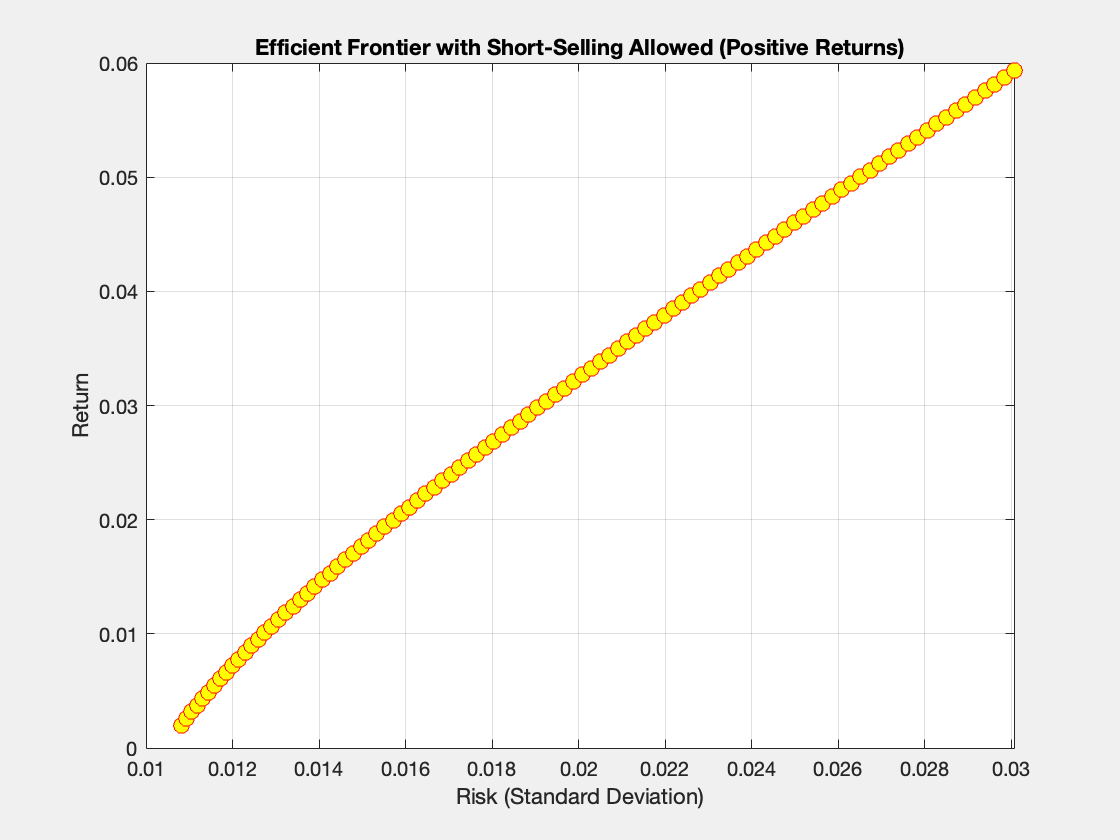

% Highlight the n portfolios on the plot
hold on
plot(risk_short, return_short, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'y')

q4

% Adjusting CEI to the Market factor
% Assume the following variables are already defined:
% CEI_RP   - The CEI risk premium (time series)
% MarketRP - The market risk premium (time series)
%correlation analysis
% Calculate the correlation between MarketRP and CEI_RP
[R , P]= corr(MarketRP, CEI_RP)

R = 0.7637

P = 6.1179e-15


%Prepare data for regression
data = table(MarketRP, CEI_RP, 'VariableNames', {'MarketRP', 'CEI_RP'});

% Run the regression of CEI_RP on MarketRP using fitlm
mdl = fitlm(data, 'CEI_RP ~ MarketRP');
plot(mdl)

% Display the regression results
disp(mdl);


Linear regression model:
    CEI_RP ~ 1 + MarketRP

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)    -0.0019285    0.0049955    -0.38605       0.70063
    MarketRP          0.55684      0.05626      9.8977    6.1179e-15


Number of observations: 72, Error degrees of freedom: 70
Root Mean Squared Error: 0.0156
R-squared: 0.583,  Adjusted R-Squared: 0.577
F-statistic vs. constant model: 98, p-value = 6.12e-15


% Proper estimate of CEI_RP
% Calculate the adjusted CEI risk premium
% The adjusted CEI premium is the part of CEI_RP that is unexplained by MarketRP
% This is given by the residuals from the regression
adjusted_CEI_RP = mdl.Residuals.Raw;


% Initial estimate vs adjusted estimate
MCEI_RP=mean(CEI_RP) %initial

MCEI_RP = 0.0440

mean_adjCEI_RP = mean(adjusted_CEI_RP)

mean_adjCEI_RP = -7.7099e-19